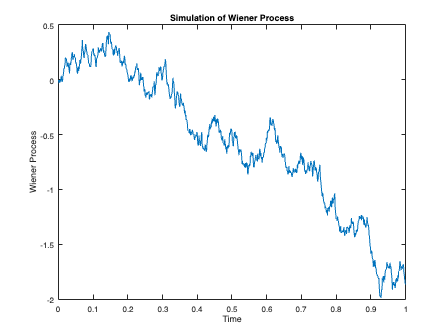

clear all;
% Define parameters
T = 1;        % Total time duration
N = 1000;     % Number of time steps
dt = T / N;   % Time step size

% Initialize the Wiener process
W = zeros(1, N+1);

% Generate normally distributed random increments and accumulate
for i = 1:N
    dW = sqrt(dt) * randn(1);
    W(i+1) = W(i) + dW;
end

% Plot the Wiener process
t = linspace(0, T, N+1);
plot(t, W)
xlabel('Time')
ylabel('Wiener Process')
title('Simulation of Wiener Process')

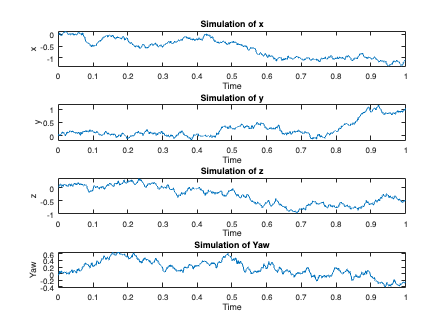

% Define parameters
T = 1;        % Total time duration
N = 1000;     % Number of time steps
dt = T / N;   % Time step size

% Initialize the states (x, y, z, yaw)
x = zeros(1, N+1);
y = zeros(1, N+1);
z = zeros(1, N+1);
yaw = zeros(1, N+1);

% Generate normally distributed random increments and accumulate for each state
for i = 1:N
    dx = sqrt(dt) * randn(1);
    dy = sqrt(dt) * randn(1);
    dz = sqrt(dt) * randn(1);
    dyaw = sqrt(dt) * randn(1);

    x(i+1) = x(i) + dx;
    y(i+1) = y(i) + dy;
    z(i+1) = z(i) + dz;
    yaw(i+1) = yaw(i) + dyaw;
end

% Plot the states over time
t = linspace(0, T, N+1);
subplot(4,1,1)
plot(t, x)
xlabel('Time')
ylabel('x')
title('Simulation of x')
subplot(4,1,2)
plot(t, y)
xlabel('Time')
ylabel('y')
title('Simulation of y')
subplot(4,1,3)
plot(t, z)
xlabel('Time')
ylabel('z')
title('Simulation of z')
subplot(4,1,4)
plot(t, yaw)
xlabel('Time')
ylabel('Yaw')
title('Simulation of Yaw')